### به نام خدا

### تمرین 4 علوم شناختی

### مهیار ملکی - 810100476

### خرداد 1401

- **2. Data Modality: Local Field Potentials  **

**2.1. Phase-Locking Value (PLV) Analysis**

`a. `Look up the filter and filtfilt commands in MATLAB documentation. Which command do you think is more suitable for filtering the data for the PLV analysis? Why?

- Filter command is more suitable in compare with filtfilt, because filtfilt performs a zero-phase digital filtering and after the filtering, the result will have zero phase distortion, but in PLV analysis we do compare the phase of two signals and calculate the diffrence of them according to formula, so it will be zero at all time !!

b. What is the purpose of baseline-normalizing the results as the final step of the PLV analysis?  

- PLV is a statistics that analysis phase difference of two channels and randomness of their relation. PLV is always between 0 and 1 (zero shows the randomness of two signals and 1 shows that two signals are synchronized). We want to know that when the subject is performing an action, are there any relation between two channels (FEF & V4). For this purpose we need two know is there any significant increase in PLV value or not. Because of that we do normalization on the fixation point period (1ms) to show better any decreae or increase of the PLV.

c. Recall the concept of shuffle correction. Can one use shuffle correction instead of baseline-normalization? 

- We want signals to be independent of the baseline time and solely correlated to the stimulation. So by this method we can shuffle the baseline time points over all trials. Then if truely there isn't any correlation between the results and baseline period, results will solely be correlated to the stimulation.

d. Implement the PLV metric and apply it on the LFP recordings contained in the provided dataset.

- function that calculate PLVs:

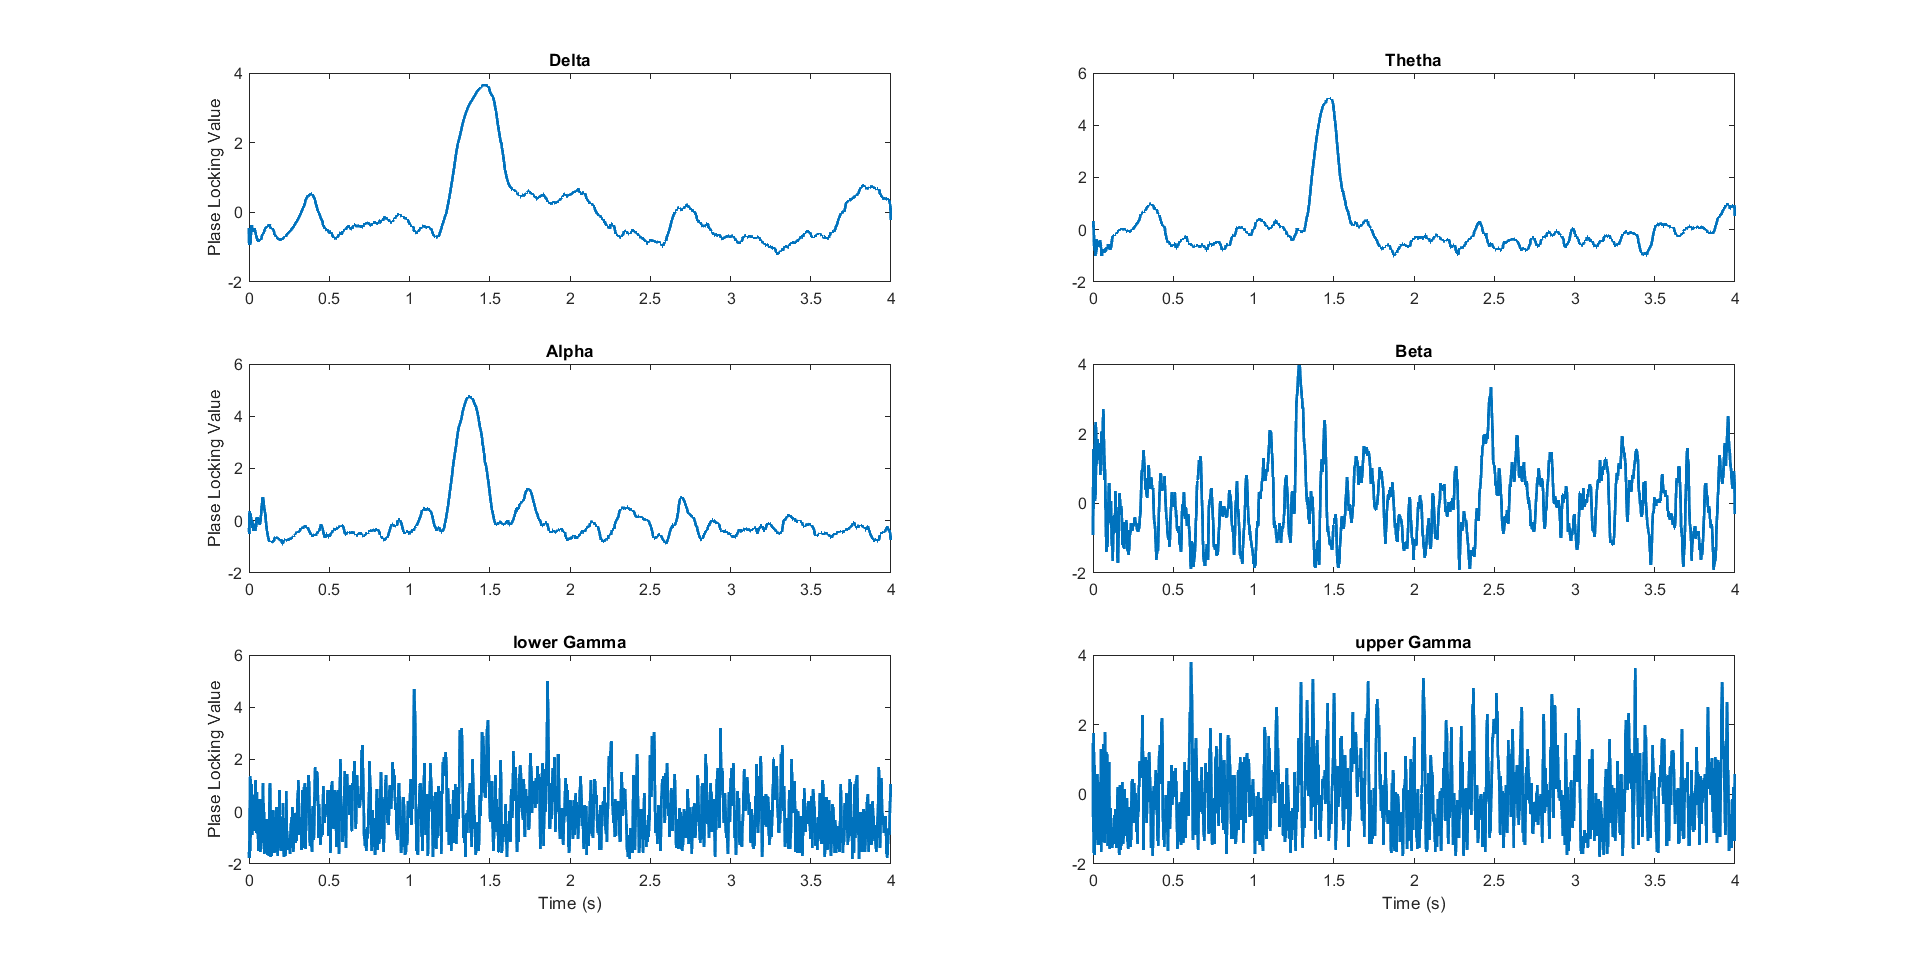

load lfp.mat
lfpdata = X_in_sessions;

% Parameters
samplerate = 1000;
order = 500;
fixation_period = 1000;
bands = {[2 4], [4 8], [8 12], [15 30], [30 80], [80 150]};
bandnames = ["Delta", "Thetha", "Alpha", "Beta", "lower Gamma", "upper Gamma"];
x = (0:size(lfpdata, 2)-1)/samplerate;

% Normalizations & plots
h = figure();
for d = 1:6
    domain = [bands{d}];
    myplv = plv(lfpdata, samplerate, domain, order);
    myplv = (myplv-mean(myplv))/std(myplv);
    subplot(3,2,d)
    plot(x, myplv, 'Linewidth', 2);
end

subplot(3,2,1)
title('Delta'); ylabel('Plase Locking Value')
subplot(3,2,2)
title('Thetha')
subplot(3,2,3)
title('Alpha'); ylabel('Plase Locking Value')
subplot(3,2,4)
title('Beta')
subplot(3,2,5)
title('lower Gamma'); xlabel('Time (s)'); ylabel('Plase Locking Value')
subplot(3,2,6)
title('upper Gamma'); xlabel('Time (s)')
set(h,'Units','normalized','Position',[0 0 1 0.9]);

e. Do you observe any increase in connectivity strength? If positive, try to assess its statistical significancy. Do permutation test with the null-hypothesis of no locking between two regions.

- For this statistical anlysis we splited the time to two groups, first the period of fixation point (1-1000ms) and second is 1000ms after the stimulus. Then we did a permutation test on the time frame of 1-2000. The results are printed under the code. 

for d = 1:6
    domain = [bands{d}];
    
    % time periods (before and after stimulus)
    fixation_time = lfpdata(:,1:fixation_period,:);
    stimulus_time = lfpdata(:,fixation_period+1:fixation_period+1000,:);
    
    % calculating plv
    plv1 = plv(fixation_time, samplerate, domain, order);
    plv2 = plv(stimulus_time, samplerate, domain, order);
    
    % test statistics
    dmiu = mean(plv2) - mean(plv1);
    
    % permutation test with 100 permuts
    n = 100;
    dmius = zeros(n,1);
    for i = 1:n
        time = randperm(fixation_period+1000);
        fixation_time = lfpdata(:,time(1:fixation_period),:);
        stimulus_time = lfpdata(:,time(fixation_period+1:fixation_period+1000),:);
        plv1 = plv(fixation_time, samplerate, domain, order);
        plv2 = plv(stimulus_time, samplerate, domain, order);
        dmius(i) = mean(plv2) - mean(plv1);
    end
    
    % ttest
    [decision, p_value] = ttest(dmius, dmiu);
    disp(['For band -> ', convertStringsToChars(bandnames(d))])
    disp(['P_Value = ', num2str(p_value)])
    if decision == 1
        disp('Null hypothesis is not rejected. So the increase of PLV value is statistically significant.')
    else
        disp('Null hypothesis is rejected. So the increase of PLV value is not statistically significant.')
    end
end

For band -> Delta


P_Value = 1.679e-103


Null hypothesis is not rejected. So the increase of PLV value is statistically significant.


For band -> Thetha


P_Value = 1.9718e-69


Null hypothesis is not rejected. So the increase of PLV value is statistically significant.


For band -> Alpha


P_Value = 1.6167e-91


Null hypothesis is not rejected. So the increase of PLV value is statistically significant.


For band -> Beta


P_Value = 6.6435e-63


Null hypothesis is not rejected. So the increase of PLV value is statistically significant.


For band -> lower Gamma


P_Value = 8.9781e-54


Null hypothesis is not rejected. So the increase of PLV value is statistically significant.


For band -> upper Gamma


P_Value = 3.0405e-23


Null hypothesis is not rejected. So the increase of PLV value is statistically significant.


**2.2. Linear Granger Causality (LGC) Analysis**

a. Describe the assumptions of the LGC method. In other words, what are the preconditions that the input time-series must meet in order for the results to be considered dependable?

- Stationary: The mean and variance of each time series do not change over time. 

- By some processings we can make our time series stationary, for example normalization and differencings the time series one or more times can do that. At worse case we can perform our analysis on smaller time windows that they are stationary.

b. Load the dataset (lfp.mat) and examine whether the data meets the preconditions of the LGC analysis? Justify your answer by plotting proper diagrams and performing statistical tests on the data.

- Here we run two tests for stationary testing (ADF & KPSS). The ADF tells that our data is non-stationary over all trials but KPSS tells that our data is stationary.

warning off
load lfp.mat
X = X_in_sessions;

% ADF unit-root test
alpha     = 0.05;   % significance level for significance test
stlags    = 30;     % number of lags for stationarity tests (or leave empty for automatic default)
ntrials   = 196;    % number of trials

[adftstat,adfcval] = mvgc_adf(X,alpha,stlags);
adfsig = adftstat > adfcval; % unit root
adfnonstat = find(adfsig);
if isempty(adfnonstat)
    fprintf('all time series are stationary by ADF test at significance %g\n',alpha);
else
    for r = 1:ntrials
        adfnonstat = find(adfsig(r,:));
        if ~isempty(adfnonstat)
            fprintf(2,'WARNING: non-stationary time series by ADF test at significance %g for trial %d\n',alpha,r);
        end
    end
end

% KPSS unit-root test
[ksstat,kscval] = mvgc_kpss(X,alpha,stlags);
kssig = ksstat > kscval; % unit root
ksnonstat = find(kssig);
if isempty(ksnonstat)
    fprintf('all time series are stationary by KPSS test at significance %g\n',alpha);
else
    for r = 1:ntrials
        ksnonstat = find(kssig(r,:));
        if ~isempty(ksnonstat)
            fprintf(2,'WARNING: non-stationary time series by KPSS test at significance %g for trial %d\n',alpha,r);
        end
    end
end

all time series are stationary by KPSS test at significance 0.05


c. Perform the following pre-processing steps on the data:

- i) Filtering: Apply a High-pass filter at 0.5Hz to remove any irrelevant low-frequency oscillations. Followed by that, apply an additional notch filter at 60Hz to remove noises incurred by the power line nearby the recording chamber.

- ii) Normalization: In each trial, find the mean and standard deviation of all samples associated with that trial. Then, following the equation below, normalize the data for each individual trial.

- iii) Stationarity: To make sure that recordings of each trial behaves as a stationary time-series, apply a first-order differentiation on each individual trial. In MATLAB, you can simply use the following command: y = diff(x)  

load lfp.mat
X = X_in_sessions;

F0 = 60;   % Interference is at 60 Hz
FH = 0.5;  % High-pass filter frequency
Fs = 1000; % Sampling frequency is 1000 Hz
BW = 6;    % Choose a bandwidth factor of 6Hz
[num1,den1] = iirnotch(F0/(Fs/2),BW/(Fs/2));

proccesed_lfp = zeros(2,4000-1,196);
for channel = 1:2
    for t = 1:196
        X(channel,:,t) = highpass(X(channel,:,t), FH, Fs);
        X(channel,:,t) = filter(num1,den1, X(channel,:,t));
        X(channel,:,t) = (X(channel,:,t) - mean(X(channel,:,t))) / std(X(channel,:,t));
        proccesed_lfp(channel,:,t) = diff(X(channel,:,t));
    end
end

d. LGC Analysis: By applying the LGC method on the data, plot the time-course of connectivity strength in both directions (i.e. V4 → FEF and FEF → V4). To calculate this time-course, you must employ the LGC method on smaller windows and slide that window from t=0s to t=4s. For this analysis, you may use window size of 150ms.

- For this part we defined a function:

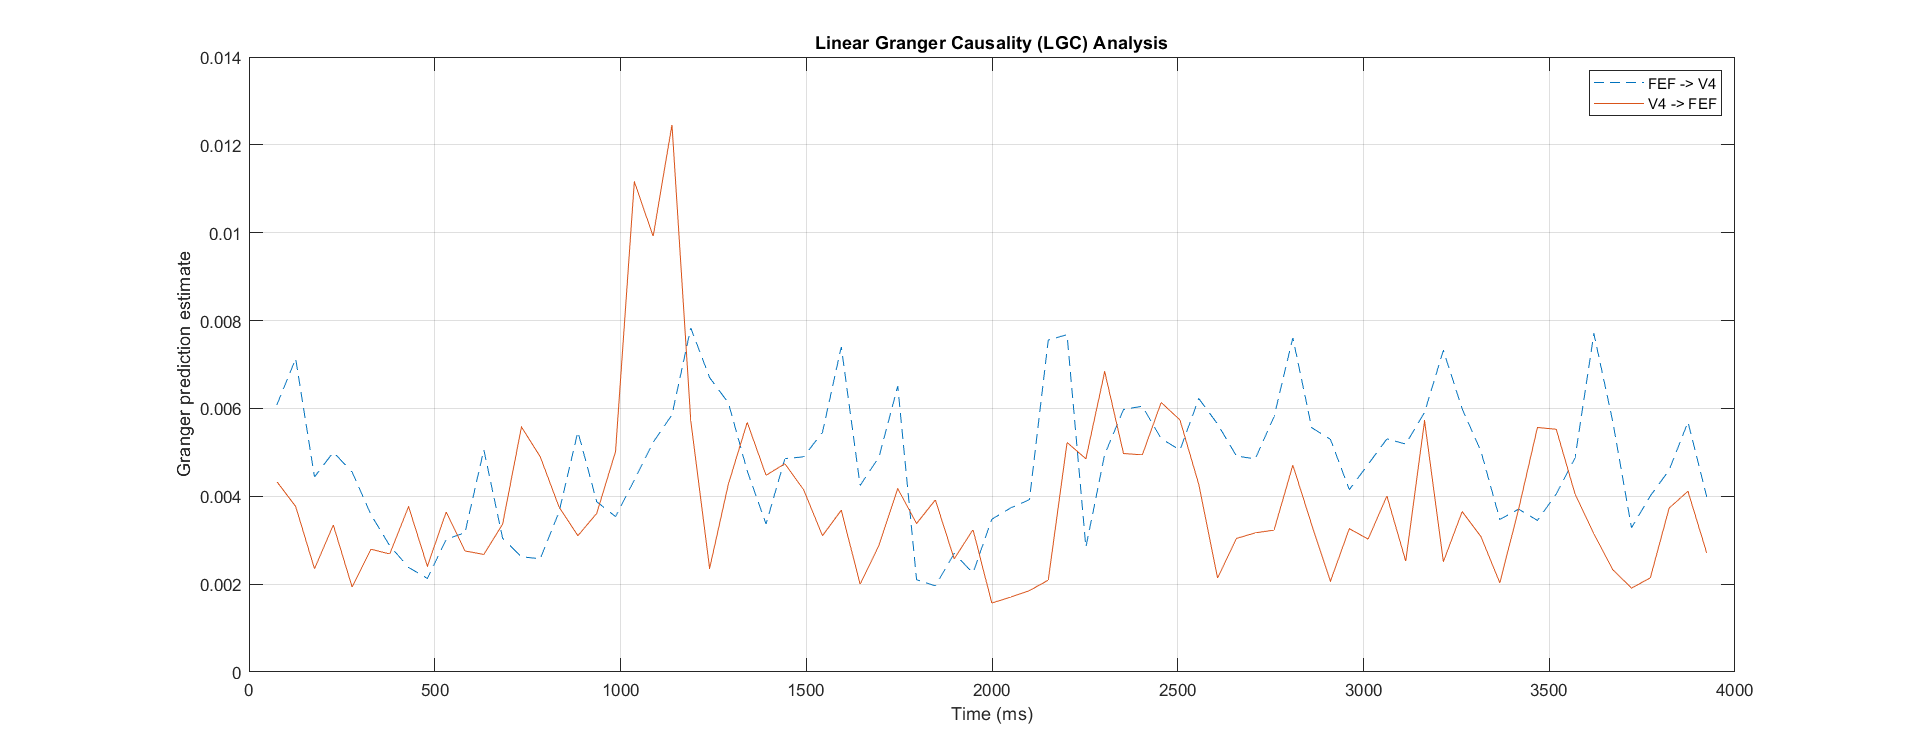

X = proccesed_lfp;    % LFP Data
ev    = 50;           % evaluate GC at every ev-th sample
wind  = 150;          % observation regression window size
nobs  = 3999;
ek    = wind:ev:nobs; % GC evaluation points
enobs = length(ek);   % number of GC evaluations

% Finding model order by AIC and BIC test
[~,~,moaic,mobic] = tsdata_to_infocrit(X, 30, 'OLS', false);
morder = min(moaic,mobic);


% Linear granger analysis
[FEF_V4,V4_FEF] = lgc(X, ev, wind, morder);

% PLotting
x = linspace(wind/2,nobs-wind/2,enobs);
h = figure();
plot(x,FEF_V4,'--',...
     x,V4_FEF)
legend('FEF -> V4','V4 -> FEF');
title('Linear Granger Causality (LGC) Analysis')
xlabel('Time (ms)')
ylabel('Granger prediction estimate')
set(h,'Units','normalized','Position',[0 0 1 0.7])
grid on

  e. Do you observe any increase in connectivity strength? How can you statistically assess the significance of your observations? Propose a method for evaluating your results and examine them by applying the proposed method on the results.

- It seems at the time when fixation period disapears FEF signal can be predicted from V4 and there is a increase in connectivity strength of this diagram. We can evaluate this hypothesis by a permutation test like PLV case. It can be seen in results that the connectivity increasation is statistically significant.

% time periods (before and after stimulus)
fixation_period = 1000;
fixation_time = X(:,1:fixation_period,:);
stimulus_time = X(:,fixation_period+1:fixation_period+1000,:);

% calculating LGC
[~,V4_FEF_1] = lgc(fixation_time, ev, wind, morder);
[~,V4_FEF_2] = lgc(stimulus_time, ev, wind, morder);

P_Value = 3.9148e-45


Null hypothesis is rejected. So the increase of PLV value is statistically significant.



% test statistics
dmiu = mean(V4_FEF_1) - mean(V4_FEF_2);

% permutation test with 50 permuts
n = 50;
dmius = zeros(n,1);
for i = 1:n
    time = randperm(fixation_period+500);
    fixation_time = X(:,time(1:fixation_period),:);
    stimulus_time = X(:,time(fixation_period+1:fixation_period+500),:);
    [~,V4_FEF_1] = lgc(fixation_time, ev, wind, morder);
    [~,V4_FEF_2] = lgc(stimulus_time, ev, wind, morder);
    dmius(i) = mean(V4_FEF_1) - mean(V4_FEF_2);
end

% ttest
[decision, p_value] = ttest(dmius, dmiu);
if decision == 1
    disp(['P_Value = ', num2str(p_value)])
    disp('Null hypothesis is rejected. So the increase of PLV value is statistically significant.')
else
    disp(['P_Value = ', num2str(p_value)])
    disp('Null hypothesis is not rejected. So the increase of PLV value is not statistically significant.')
end

f. Do you see any congruence between the results of PLV analysis and LGC analysis? Explain.

- There is a peak in LGC (V4->FEF) value at the end of fixation period and PLV value starts to increase when the peak disapears. So there is an inverse relation between these two values. It's because when PLV increases the phase of signals are close together, so there is no lag between two signals to predict one by another.

`end.`